Zonal Wavefront Reconstruction

Sections below are only guaranteed to run correctly when they aresuccessively executed

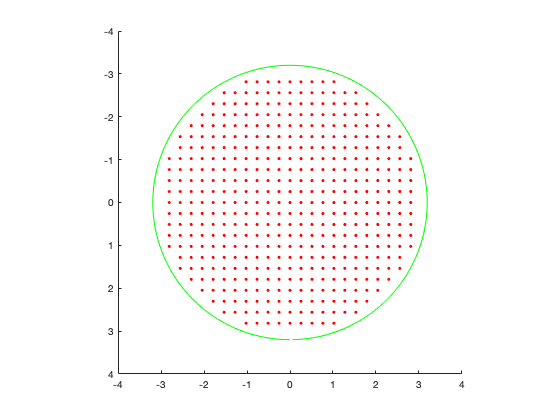

clearvars
pitchLenslet = 256e-6;  % sampling rate (subaperture size) in m     
pitchPixel = 6.4e-6;                % physical pixel size
if pitchLenslet == 256e-6
    datFilename = "Centroid_z7_1um_256um_6.4mm.1.dat";
    focal = 5.9041e-3;                      % lenslet focal length
else
    datFilename = "Centroid_z7_1um_64um_6.4mm.1.dat";
    focal = 1.4761e-3
end

% Evaluate analytical expression for derivative of coma at reference grid
% sampling locations
[x, y, dx, dy] = load2WavefrontDifferences(datFilename);
x = (x - mean(x)) * pitchPixel;
y = (y - mean(y)) * pitchPixel;

scatter(x * 1e3, y * 1e3, '.r'), axis square ij
hold on
t = 1:360;
sd = 3.2;           % pupil semidiameter (mm)
plot(sd * sind(t), sd * cosd(t), 'g')
hold off

Set up wavefront slopes and execute iterative FFT algorithm

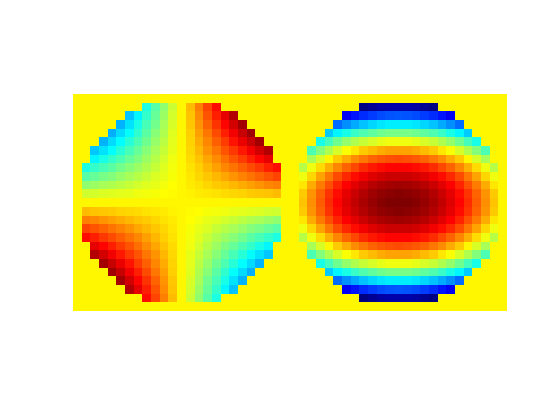

u = unique(x);
N = length(u);
A = false(N);
for idx = 1:N
    len = length(find(x == u(idx)));
    a = round(0.5 * (N - len)) + 1;
    b = a + len - 1;
    A(a:b,idx) = true;
end

% 'measured' wavefront slope meshgrids
Mx = zeros(N);
My = zeros(N);
k = 1;
for idx = 1:numel(A)
    if A(idx)
        Mx(idx) = pitchPixel * dx(k) / focal;
        My(idx) = pitchPixel * dy(k) / focal;
        k = k + 1;
    end
end

Mx = padarray(Mx', [1 1]);
My = padarray(My', [1 1]);
A = padarray(A, [1 1]);
imagesc([Mx My]), axis image off

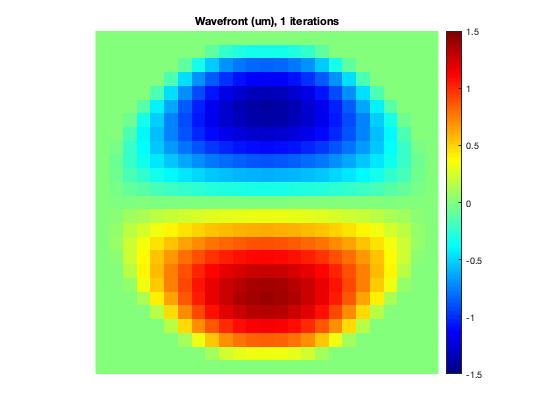

% Reconstruct wavefront from slope data
[W, rms] = zonalIterativeFourier(Mx, My, A, pitchLenslet, 1);

% draw wavefront
imagesc(W * 1e6), axis image off
caxis([-1.5 1.5])
title(['Wavefront (um), ' num2str(numel(rms) - 1) ' iterations'])
colormap('jet')
colorbar
axis image off

function [x, y, dx, dy] = load2WavefrontDifferences(filename)
%LOAD2WAVEFRONTDIFFERENCES positions and difference output are in pixels

% extract raw numbers
fid_temp = fopen(filename,'r');
fgets(fid_temp);
fgets(fid_temp);
data = fscanf(fid_temp, '%f\t');
fclose(fid_temp);

% order data so each row represents single subaperture
data = reshape(data, [5, length(data) / 5])';

% sampled positions (reference centroids)
x = data(:,2);
y = data(:,3);

% wavefront differences
dx = -(data(:,4) - data(:,2)); 
dy = -(data(:,5) - data(:,3));
dx = dx - mean(dx);
dy = dy - mean(dy);

end